mainFolder = fullfile(pwd, "AudioManip-Main");

% Ensure main folder exists
if ~exist(mainFolder, 'dir')
    mkdir(mainFolder);
end

% Load processed normal and abnormal files
normalFilesSVM = dir(fullfile(mainFolder, "sounddata*.wav"));
abnormalFilesSVM = dir(fullfile(mainFolder, "abnormalsounddata*.wav"));

% Convert file names into string arrays and sort them
normalListSVM = string({normalFilesSVM.name});
abnormalListSVM = string({abnormalFilesSVM.name});
natsortfiles(normalListSVM);
natsortfiles(abnormalListSVM);

% Combine normal and abnormal audio file lists
allAudioFilesSVM = [normalListSVM, abnormalListSVM];
numFilesSVM = length(allAudioFilesSVM);

% Define processing parameters
fixedLength = 1000;
chNum = 1;

% Preallocate waveform matrix with zeros
allWaveformsSVM = zeros(numFilesSVM, fixedLength);

% Process each file: load, convert to mono, trim/pad, normalize
for i = 1:numFilesSVM
    fileName = fullfile(mainFolder, allAudioFilesSVM(i));
    if exist(fileName, 'file')
        [y, Fs] = audioread(fileName);
        if size(y, 2) > 1
            y = mean(y, 2);
        end
        if length(y) > fixedLength
            y = y(1:fixedLength);
        elseif length(y) < fixedLength
            y = [y; zeros(fixedLength - length(y), 1)];
        end
        y = (y - mean(y)) / std(y);
        allWaveformsSVM(i, :) = y';
    else
        warning("Processed file %s not found.", fileName);
    end
end

% Reshape waveform data for machine learning input
waveformDataSVM = reshape(allWaveformsSVM, numFilesSVM, fixedLength);

% Preallocate feature matrix and labels
allFeaturesSVM = zeros(numFilesSVM, size(generateAudioFeatures(fileName, chNum), 2) + size(generateFFTFeatures(fileName, chNum, 1024), 2));
allLabelsSVM = [zeros(1, length(normalListSVM)), ones(1, length(abnormalListSVM))];

% Extract features for each audio file
for i = 1:numFilesSVM
    fileName = fullfile(mainFolder, allAudioFilesSVM(i));
    if exist(fileName, 'file')
        timeFreqFeaturesSVM = generateAudioFeatures(fileName, chNum);
        fftFeaturesSVM = generateFFTFeatures(fileName, chNum, 1024);
        featureVectorSVM = [table2array(timeFreqFeaturesSVM), table2array(fftFeaturesSVM)];
        allFeaturesSVM(i, :) = featureVectorSVM;
    else
        warning("Feature extraction skipped for missing file: %s", fileName);
    end
end

% Create feature table with labels
featureNamesSVM = [timeFreqFeaturesSVM.Properties.VariableNames, fftFeaturesSVM.Properties.VariableNames];
featureTableSVM = array2table(allFeaturesSVM, 'VariableNames', featureNamesSVM);
featureTableSVM.Label = allLabelsSVM';

% Convert features to numeric matrix
featureMatrixSVM = table2array(featureTableSVM(:, 1:end-1));

disp("All features processed and ready for SVM analysis!");

All features processed and ready for SVM analysis!


SVM Accuracy: 96.49%


Iteration Number 1.000000

SVM Accuracy: 93.89%


Iteration Number 2.000000

SVM Accuracy: 95.93%


Iteration Number 3.000000

SVM Accuracy: 95.21%


Iteration Number 4.000000

SVM Accuracy: 95.12%


Iteration Number 5.000000

SVM Accuracy: 94.78%


Iteration Number 6.000000

SVM Accuracy: 95.02%


Iteration Number 7.000000

SVM Accuracy: 94.34%


Iteration Number 8.000000

SVM Accuracy: 94.97%


Iteration Number 9.000000

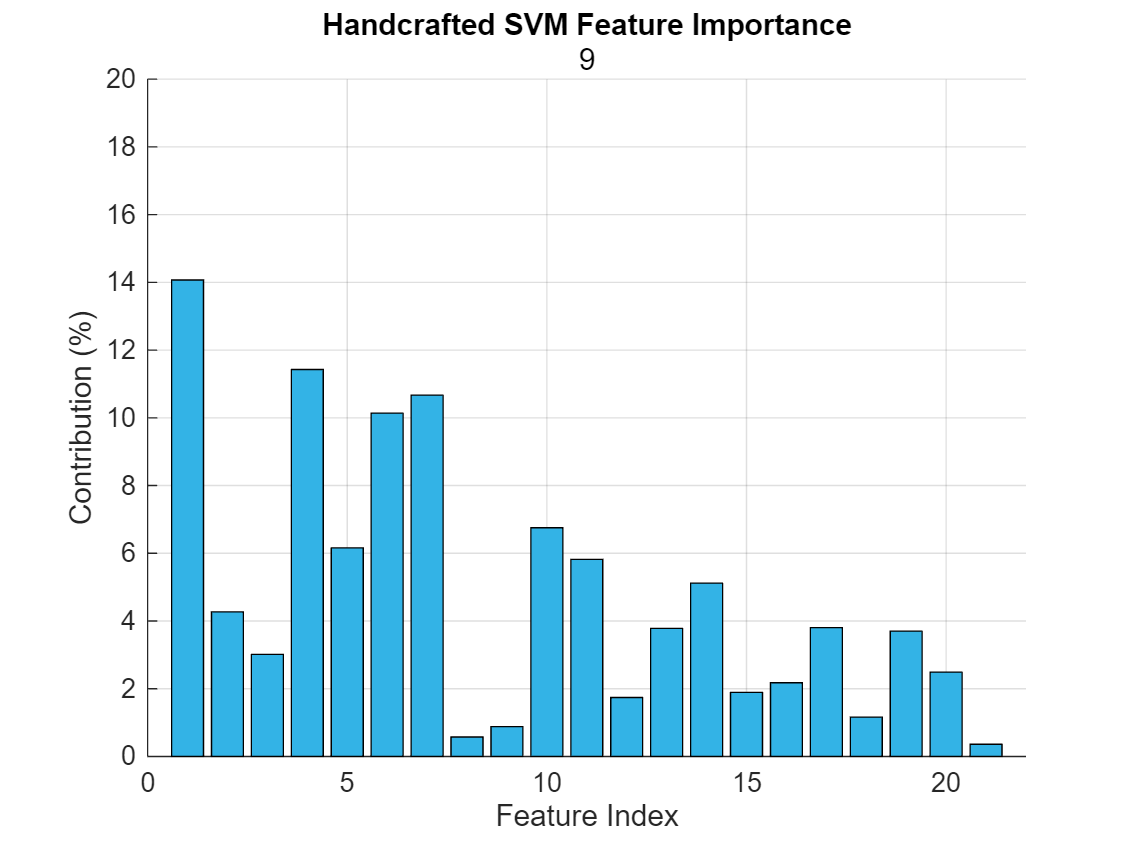


% Note: I know this portion of the code is a bit sloppy with the          % 
% transposition of the label arrays YTrain and YTest, but since the lines %
% of code all work correctly I dare not touch it for now. That being said,%
% rearrange any of this as you see fit if you have similar and/or more    %
% knowledge on how this should be working.                                %

perfMod = 0.9;

for perfModiter = 0.1:0.1:perfMod
    % Split Data 
    cv = cvpartition(allLabelsSVM, 'HoldOut', perfModiter);
    XTrain = featureMatrixSVM(training(cv), :);
    YTrain = allLabelsSVM(training(cv));
    XTest = featureMatrixSVM(test(cv), :);
    YTest = allLabelsSVM(test(cv));
    
    % Train SVM Model
    svmModel = fitcsvm(XTrain, YTrain', 'KernelFunction', 'linear', 'Standardize', true);
    
    % Predict on Test Data
    YPred = predict(svmModel, XTest);
    
    % Accuracy
    accuracy = sum(YPred == YTest') / length(YTest');
    fprintf('SVM Accuracy: %.2f%%\n', accuracy * 100);
    fprintf('Iteration Number %f%\n', perfModiter/0.1);
    
    svmWeights = svmModel.Beta;
    featureContributionsvm = abs(svmWeights) / sum(abs(svmWeights)) * 100;
    bar(featureContributionsvm);
    xlabel('Feature Index');
    ylabel('Contribution (%)');
    title('Handcrafted SVM Feature Importance');
    grid on;

     % Create bar plot that updates smoothly
    clf; % Clear figure for fresh plot
    hold on;

    % Animate the bars growing
    numFeaturessvm = length(featureContributionsvm);
    barHeights = zeros(1, numFeatures);
    numSteps = 20;  % Number of steps for animation

    for step = 1:numSteps
        % Smoothly update bar heights
        barHeights = featureContributionsvm * (step / numSteps);
        bar(barHeights, 'FaceColor', [0.2, 0.7, 0.9]);

        % Labels and formatting
        xlabel('Feature Index');
        ylabel('Contribution (%)');
        title('Handcrafted SVM Feature Importance',  perfModiter/0.1);
        axis([0 numFeaturessvm+1 0 20]);
        grid on;
        drawnow; 
    end

    hold off;

end

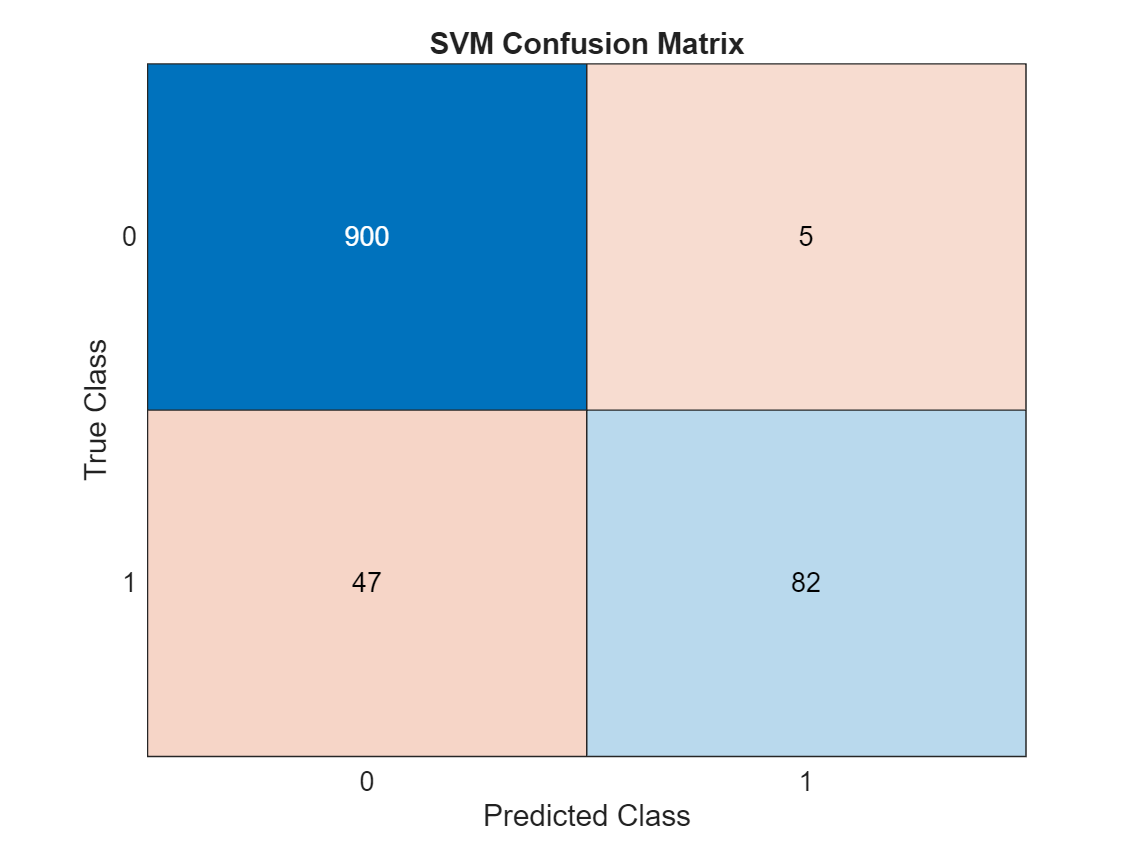

Avg. Overall Accuracy: 94.980000 

% Confusion Matrix didn't want to change in real time with bargraph so %
% it is now in its own space for the time being.                       %
confusionchart(YTest', YPred);
title('SVM Confusion Matrix');